## AAE364 HW9 MATLAB CODE

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE364\matlab\matlab_output\hw9';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

### B-6-19

% Define OLTF G(s)
num = 16;                 % numerator 
den = conv([1 0],[1 4]);  % denominator

% Desired pole
sd = -2 + 2i*sqrt(3);

% Compute deficiency angle [deg]
psi = calc_ang_deficiency(num,den,sd);

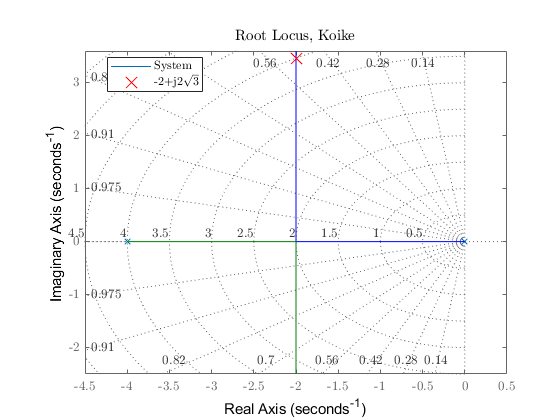


% Plotting the RL (negative feedback)
fig1 = figure("Renderer","painters");
    rlocusplot(tf(num,den)); sgrid;
    title('Root Locus, Koike',"Interpreter","latex")
    hold on
    plot(real(sd),imag(sd),'xr','MarkerSize',12)
    hold off  
    ylim([-2.5 3.6])
    legend('System','-2+j2$\sqrt{3}$',"location","best")
saveas(fig1,fullfile(fdir,'B-6-19_RL.png'));

### B-6-21

% Define OLTF G(s)
num = [0 10];             % numerator 
den = conv([1 0],[1 2]);  % denominator
den = conv(den,[1 5]);

% Desired pole
Kv = 50;  % [s-1]
sd = -2 + 2i*sqrt(3);

% Compute deficiency angle [deg]
psi = calc_ang_deficiency(num,den,sd)

psi = 79.1066

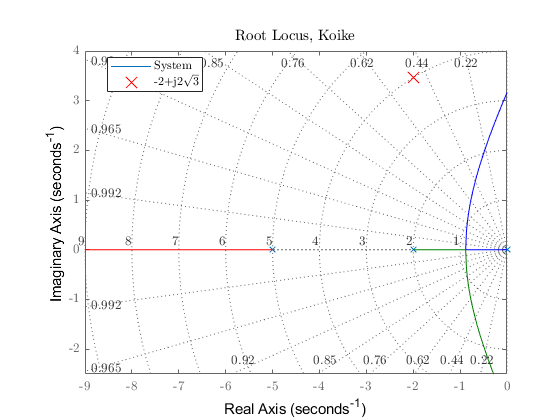


% Plotting the RL (negative feedback)
fig2 = figure("Renderer","painters");
    rlocusplot(tf(num,den)); sgrid;
    title('Root Locus, Koike',"Interpreter","latex")
    hold on
    plot(real(sd),imag(sd),'xr','MarkerSize',12)
    hold off  
    ylim([-2.5 4.0])
    legend('System','-2+j2$\sqrt{3}$',"location","best")
saveas(fig2,fullfile(fdir,'B-6-21_RL.png'));

% Finding z1, p1 (beta*z1), and Kc
Kc = Kv;

z1_lim = imag(sd)/tand(psi) - real(sd);  % condition for z1
theta1 = atan(7.8743*sind(psi)/(7.8743*cosd(psi) - 1));
theta1_deg = rad2deg(theta1);
z1 = imag(sd)/tan(theta1) + 2;
theta2_deg = theta1_deg - psi;
beta = (imag(sd)/tand(theta2_deg) + 2)/z1;

% lag component 
p2 = 0.01;
mag_lag = abs((sd + p2*beta)/(sd + p2));
ang_lag = rad2deg(angle(sd + p2*beta) - angle(sd + p2));

### B-6-23

% Design requirements 
Mp = 25;  % [%]
ts = 5;  % settling time 
% Design parameters
zeta = calc_zetaFromMOS_or_MOSFromzeta(Mp,"zeta");
wn = 4/5/zeta;
% Desired pole (positive imag)
sd = -zeta*wn + wn*1i*sqrt(1 - zeta^2);

% OLTF
num = [0 1];
den = conv([1 0],[1 0]);
den = conv(den,[1 4]);

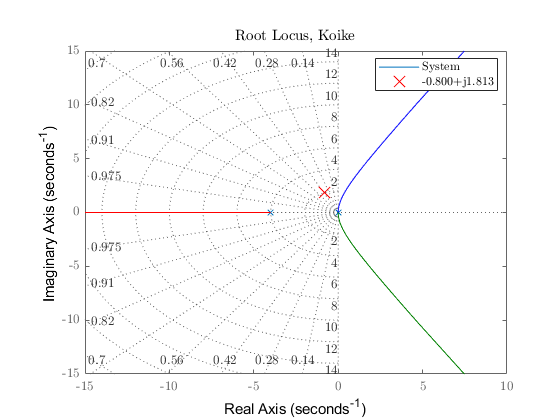

% Plotting the RL (negative feedback)
fig3 = figure("Renderer","painters");
    rlocusplot(tf(num,den)); sgrid;
    title('Root Locus, Koike',"Interpreter","latex")
    hold on
    plot(real(sd),imag(sd),'xr','MarkerSize',12)
    hold off  
    sd_txt = sprintf("%0.3f+j%0.3f",real(sd),imag(sd));
    legend('System',sd_txt,"location","best")
saveas(fig3,fullfile(fdir,'B-6-23_RL.png'));

% Angle deficiency 
psi = calc_ang_deficiency(num,den,sd)

psi = 77.1545


% Selecting zc, pc, and K
zc_lim = imag(sd)/tand(psi) - real(sd)  % condition for zc

zc_lim = 1.2134

zc = 1.2;
theta1_deg = atand(imag(sd)/(zc + real(sd)));
theta2_deg = theta1_deg - psi;
pc = imag(sd)/tand(theta2_deg) - real(sd);
% Calculate K 
syms K
Gc = (sd + zc)/(sd + pc);
G = 1/sd^2/(sd + 4);
eqn = K*abs(Gc*G) == 1

$$eqn = \frac{4604232588844473\,K}{9223372036854775808}=1$$

K = double(solve(eqn,K));

### B-6-24

% Design parameters
zeta = 0.5;
ts = 2;
wn = 4/ts/zeta

wn = 4

% Desired pole (positive imag)
sd = -zeta*wn + wn*1i*sqrt(1 - zeta^2)

sd = -2.0000 + 3.4641i

Kh = 99/5000;

### B-6-26

% RL
num = [0 2];
den = [1 2 2 0];
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig1] = rootLocus_stepBystep_negFeedback(num,den)

q =     -6    -8    -4


d = 4

rts =   -0.6667 + 0.4714i
  -0.6667 - 0.4714i


$$Re = 2\,k=2\,w^{2}$$

$$Im = 0=w^{3}-2\,w$$

poles =    0.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i



zrs =

  0×1 empty double column vector



angs =     60   180   300


sigma = -0.6667


bi_pt =

  0×1 empty double column vector



T_P = 3×3 table
    POLES    RADIUS     DEGREES
    _____    _______    _______

     0+0i     3.1416      180  
    -1+1i    -0.7854      -45  
    -1-1i     7.0686      405  



T_Z =

     []



k =      0
     2
     2


w =          0
   -1.4142
    1.4142


fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


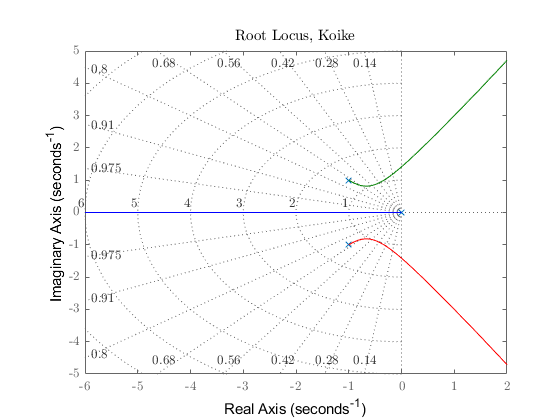

saveas(fig1,fullfile(fdir,"B-6-26_RL.png"))

% Find gain, K when zeta = 0.5
zeta = 0.5;

syms K wn s
assume(K,'real');
assume(wn,'real');
p = -zeta*wn + wn*1j*sqrt(1 - zeta^2);
RHS = (s*(s^2 + 2*s + 2))

$$RHS = s\,\left(s^{2}+2\,s+2\right)$$

RHS = subs(RHS,s,p)

$$RHS = -\left(\frac{\mathrm{wn}}{2}-\frac{\sqrt{3}\,\mathrm{wn}\,\mathrm{i}}{2}\right)\,\left(2+{\left(\frac{\mathrm{wn}}{2}-\frac{\sqrt{3}\,\mathrm{wn}\,\mathrm{i}}{2}\right)}^{2}-\mathrm{wn}+\sqrt{3}\,\mathrm{wn}\,\mathrm{i}\right)$$

RHS = expand(RHS)

$$RHS = {\mathrm{wn}}^{3}-{\mathrm{wn}}^{2}-\mathrm{wn}+\sqrt{3}\,\mathrm{wn}\,\mathrm{i}-\sqrt{3}\,{\mathrm{wn}}^{2}\,\mathrm{i}$$

eqn1 = 2*K == -real(RHS)

$$eqn1 = 2\,K=-{\mathrm{wn}}^{3}+{\mathrm{wn}}^{2}+\mathrm{wn}$$

eqn2 = 0 == -imag(RHS)

$$eqn2 = 0=\sqrt{3}\,{\mathrm{wn}}^{2}-\sqrt{3}\,\mathrm{wn}$$

res = solve([eqn1 eqn2],[wn K]);
wn = double(res.wn)

wn =      0
     1


Kh = double(res.K)

Kh =          0
    0.5000


Kh = nonzeros(Kh)

Kh = 0.5000

### P2

q =    -2.2114   -1.3866   -0.2806   -0.1522


d =     1.2226    0.4202    0.0361


rts =   -0.6052 + 0.0000i
  -0.0109 + 0.3370i
  -0.0109 - 0.3370i


$$Re = \frac{19\,k}{100}=\frac{1477\,w^{2}}{2000}$$

$$Im = \frac{11057\,k\,w}{10000}=w^{3}-\frac{1001\,w}{1250}$$

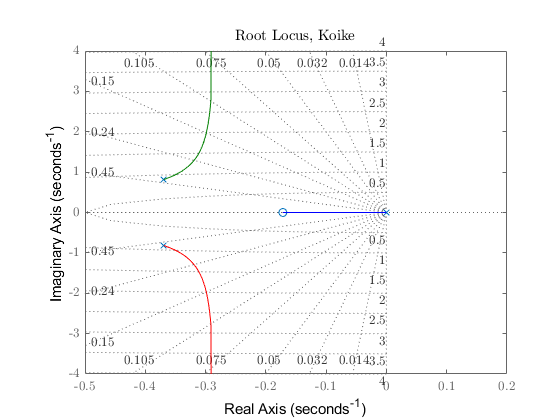

% Define system
num = [1.1057 0.1900];
den = [1 0.7385 0.8008 0];
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig1] = rootLocus_stepBystep_negFeedback(num,den);

% Design parameters
zeta = calc_zetaFromMOS_or_MOSFromzeta(10,"zeta");
wn = 2/zeta;
% Desired pole (positive imag)
sd = -zeta*wn + wn*1i*sqrt(1 - zeta^2);
% Angle deficiency
psi = calc_ang_deficiency(num,den,sd)

psi = 67.5654

% Find z_lead
syms z_lead
assume(z_lead,{'real','positive'})
eqn = angle(sd + z_lead) == deg2rad(psi);
z_lead = double(solve(eqn,z_lead))

z_lead = 3.1266


% Find K1
syms K1 
num2 = conv(num,[1 z_lead]);
G = create_TF_expression(num2,den);  % Expression with "syms" of "s"
G_sd = subs(G,s,sd);
eqn = K1*abs(G_sd) == 1;
K1 = double(solve(eqn,K1))

K1 = 3.0950

% Find z_lag
z_lag = 0.01;
d_ang = rad2deg(angle(sd + z_lag) - angle(sd))

d_ang = -0.1368

% Find K2
syms K2
num3 = conv(num2,[1 z_lag]);
den2 = conv(den,[1 0]);
G = create_TF_expression(num3,den2);
G_sd = subs(G,s,sd);
eqn = K1*K2*abs(G_sd) == 1;
K2 = double(solve(eqn,K2))

K2 = 1.0017


% Find K
K = K1*K2

K = 3.1004

% Plot RL
fig6 = figure("Renderer","painters")

fig6 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


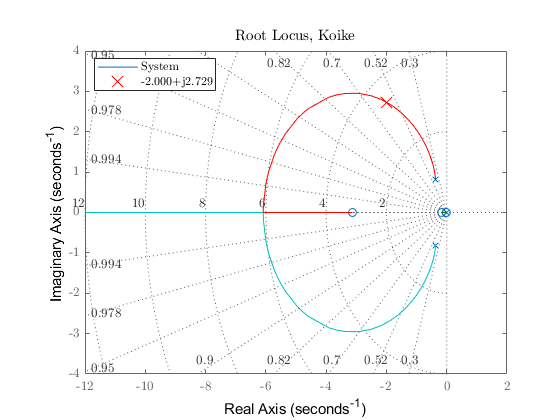

    rlocus(tf(K*num3,den2))
    sgrid
    title("Root Locus, Koike",'Interpreter',"latex")
    hold on
    plot(real(sd),imag(sd),'xr','MarkerSize',12)
    hold off  
    sd_txt = sprintf("%0.3f+j%0.3f",real(sd),imag(sd));
    legend('System',sd_txt,"location","best")
saveas(fig6,fullfile(fdir,'P2_RL_new.png'));